# **Vision Artificial. GIEC y GITT.**

# **	Sistemas de Vision Artificial. GIC, GII y GISI.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Tema 5: Kmeans (Unsupervised Learning)

## Primera parte

Nota: Se necesita tener instalada la Toolbox: "**statistics and Machine Learning**"

El objetivo de este ejercicio es hacer **agrupamiento** con **k-means **utilizando la base de datos  `fisheriris.mat`, que es un conjunto de datos de clasificación multiclase muy sencillo. Introducido por el estadístico y biólogo británico *Ronald Fisher* en su artículo de 1936. Contine 150 muestras, 50 muestras para cada una de las tres especies de flores Iris {`setosa, versicolor` y `virginica`}. Cada muestra contiene 4 características de las flores en el siguiente orden: 

- Longitud del sépalo.

- Anchura del sépalo.

- Longitud del pétalo.

- Anchura del pétalo

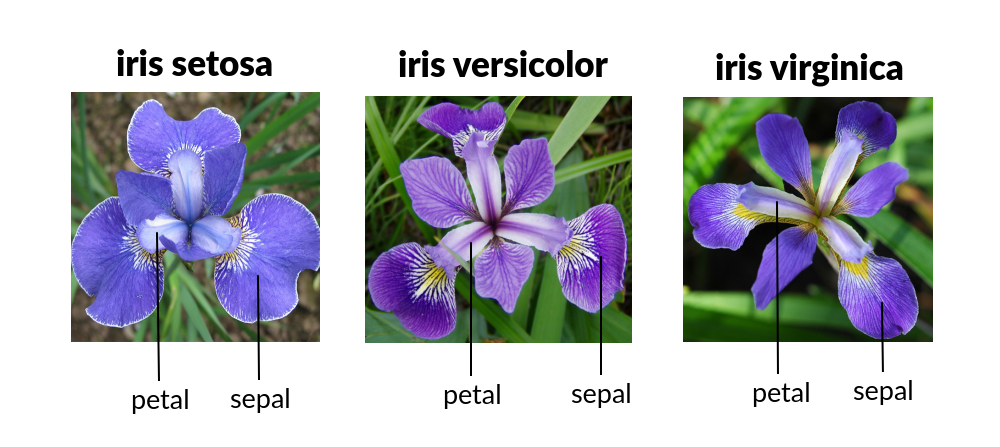

Los pasos que se deben realizar son:

- Cargar sólo la longitud y anchura del sépalo de la base de datos. 

- Visualizar los datos.

- Realizar el agrupamiento con el algoritmo k-Means.

- Visualizar el resultado del clustering.

Al cargar la base de datos` 'fisheriris'` (Se necesita tener instalada la Toolbox: "statistics and Machine Learning") se cargan las variables  `meas`, que contiene `[longitud sépalo, anchura sépalo, longitud pétalo, anchura pétalo] `en ese orden, y la variable `species`, que contiene la etiqueta de cada muestra. 

**Se pide:**

- Seleccione sólo la **longitud y anchura del sépalo** en la variable `'data_iris'` y muestre los resultados.

clear all;
close all;

% CARGAR LA BASE DE DATOS Y VISUALIZARLA

% carga las siguientes variables:
% meas: contiene los valores de las 150 muestras en el siguiente orden:
%       [longitud sépalo, anchura sépalo, longitud pétalo, anchura pétalo] 
% species: en un cell array con las 150 etiquetas de cada especie {setosa}, {versicolor} o {virginica}
load fisheriris % Se necesita tener instalada la Toolbox: "statistics and Machine Learning"

data_iris = []; % COMPLETAR AQUÍ !!! <---

% covierte el array en 'categorical'
label_iris = categorical(species);
% cell array que contienen las etiquetas de las 3 categorías
names_iris = categories(label_iris);

% visualiza los datos
figure
plot(data_iris(:,1),data_iris(:,2),'b+','MarkerSize',5);

Index in position 2 exceeds array bounds.

xlabel('Sepal length');
ylabel('Sepal width');
title('fisheriris dataset');
grid;

**Se pide:**

- Complete la variable llamada `'C_init'`, en la que se guardarán los valores iniciales de los 3 centroides, con 3 valores aleatorios (Utilice la función [`rand`](https://es.mathworks.com/help/matlab/ref/double.rand.html?s_tid=srchtitle_support_results_1_rand)) entre los valores mínimo y máximo de la longitud y anchura del sépalo (utilice las funciones [`min` ](https://es.mathworks.com/help/matlab/ref/min.html?searchHighlight=min&s_tid=srchtitle_support_results_1_min)y [`max`](https://es.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle_support_results_1_max)). Ejecute el código varias veces (cambie el valor de `'MaxIter'` si fuera necesario) y explique los resultados que obtiene el algoritmo k-means en cada iteración. ¿qué representa `'iter'`, `'num'`  y `'sum'`?.


% CLUSTERING
 
% clusters
k = 3; 

% valores iniciales para los centroides
C_init =  []; % COMPLETAR AQUÍ !!! <---

% número máximo de iteraciones
MaxIter = 10; 

% k-Means
[idx, C, sumd, D] = kmeans(data_iris, k, 'Start', C_init, 'MaxIter', MaxIter, 'Display', 'iter');

figure
gscatter(data_iris(:,1),data_iris(:,2),idx)
xlabel('Sepal length');
ylabel('Sepal width');
title('kMeans clustering');
hold on;
plot(C(:,1),C(:,2),'kx','MarkerSize',10, 'LineWidth',2)
legend('Cluster 1','Cluster 2','Cluster 3','Cluster Centroid');
hold off
grid;

    Hay que tener en cuenta que este es un algoritmo no supervisado por lo que los índices de salida (**idx**) no se corresponden con los nombres de las flores. Sin embargo, si queremos saber cómo de bien ha realizado el algorimto k-Means el agrupamiento debemos relacionar cada cluster con su etiqueta correspondiente. Sabemos que los datos de entrada (`data_iris`) están ordenados siguiendo la siguiente distribución: 

- Los datos del 1 al 50 son '`setosa`'.

- Los datos del 51 al 100 son '`versicolor`'.

- Los datos del 101 al 150 son '`virginica`'. 

    Para asignar cada índice con su correspondiente etiqueta se va a suponer que el clasificador k-means ha hecho un buen trabajo y el valor que más se repite (la moda) entre los primeros 50 datos es '`setosa`', en los siguientes 50 datos es '`versicolor`' y en los últimos 50 es '`virginica`'.

**Se pide:**

- Calcule la moda, con la función [mode](https://es.mathworks.com/help/matlab/ref/mode.html?searchHighlight=mode&s_tid=srchtitle_support_results_1_mode), de los índices que ha asignado k-means a los datos de entrada, teniendo en cuenta la distribución que se ha indicando anteriormente, asignando el índice correspiendiente a cada clase utilizando las variables: `setosa_idx, versicolor_idx o virginica_idx`. Ejecute el código y visualice el resultado.

% Evaluación

setosa_idx = []; % COMPLETAR AQUÍ !!! <---
versicolor_idx = []; % COMPLETAR AQUÍ !!! <---
virginica_idx = []; % COMPLETAR AQUÍ !!! <---

% Nombra las categorías haciendo coincidir los valores de categoría en [setosa_idx versicolor_idx virginica_idx]
% con los nombres correspondientes en {'setosa' 'versicolor' 'virginica'}.
label_kmeans = categorical(idx,[setosa_idx versicolor_idx virginica_idx],{'setosa' 'versicolor' 'virginica'});

% Fisher''s Iris dataset
figure;
hold on

% setosa
plot(data_iris(1:50,1),data_iris(1:50,2),'ro','MarkerSize',12)
% versicolor
plot(data_iris(51:100,1),data_iris(51:100,2),'go','MarkerSize',12)
% virginica
plot(data_iris(101:150,1),data_iris(101:150,2),'bo','MarkerSize',12)
% k-means
plot(data_iris(idx==setosa_idx,1),data_iris(idx==setosa_idx,2),'r.','MarkerSize',12)
plot(data_iris(idx==versicolor_idx,1),data_iris(idx==versicolor_idx,2),'g.','MarkerSize',12)
plot(data_iris(idx==virginica_idx,1),data_iris(idx==virginica_idx,2),'b.','MarkerSize',12)

xlabel('Sepal length');
ylabel('Sepal width');
hold off

grid on;
legend('setosa','versicolor', 'virginica', 'Cluster 1','Cluster 2','Cluster 3','Location','bestoutside')
title ('Fisher''s Iris dataset vs K-Means Clustering')

**Se pide:**

- Calcule la matriz de confusión del algoritmo K-means usando la función [confusionmat](https://es.mathworks.com/help/stats/confusionmat.html?searchHighlight=confusionmat&s_tid=srchtitle_support_results_1_confusionmat) y guarde el valor en la variable `CM_kmeans`, utilice esta matriz para calcular la precisión (accuracy) y guardela en la variable `ACC1`. 

- Por último, cambie los datos de entrada por la** longitud y anchura de los pétalos **y vuelva a ejecutar todo el código, guardando la precisión (accuracy) en la variable `ACC2` y compárela con `ACC1`, ¿cuál es mejor?

CM_kmeans = []; % COMPLETAR AQUÍ !!! <---
figure
confusionchart(CM_kmeans);
ACC1 =  []; % COMPLETAR AQUÍ !!! <---